**Talleres 13, 14 y 15 – Modelo de un péndulo simple**

**Objetivo:**

Utilizar un método numérico para dar solución a la ecuación de estado no lineal de un péndulo simple. Además, intepretar los resultados al modificar diferentes parámetros a partir de la respuesta temporal y el diagrama de fase.

**Enunciado:**

Dada la siguiente la siguiente ecuación de estado de segundo orden no lineal de un modelo de un péndulo simple con fuerza tangencial, resolverla utilizando el método numérico de Runge-Kutta implementado en la función ode45 de MATLAB. 

                                    
$$x_1 =x_2$$


                                    
$$x_2 =-\frac{g}{l}\textrm{sen}\left(x_1 \right)-\frac{f}{m}x_2 +\frac{u}{m*l}$$


- Con los parámetros

                ~ $\theta$ = ángulo respecto a la vertical

                ~ $\omega$ = velocidad

                ~ *u* = fuerza externa

                ~ *l* = longitud del hilo

                ~ *m* = masa del cuerpo

                ~ *f* = coeficiente de fricción

                ~ *g* = gravedad

- Condicion inicial:

                ~ $\theta$ = 0

                ~ $\omega$ = 0

                ~ *u* = 1

                ~ *l* = 2

                ~ *m* = 1

                ~ *f* = 0.2

                ~ *g* = 9.8

**1.  Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones temporales con una entrada u = 1. ¿Para que valor máximo de la entrada el sistema rotará indefinidamente?**

- **Solución del sistema para u = 1 **

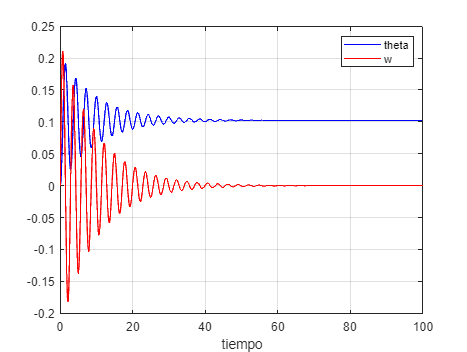

%solución del sistema con u=1
syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0.2; u=1;

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));


f = odeFunction([f1 f2],[x1 x2]);%Parte derecha de la ecuación de estado de manera numérica

h = 0.1;

tmin = 0;
tmax = 100;
tspan = tmin:h:tmax;

ci = [0 0]; 
[t,x] = ode45(f,tspan,ci);

theta = x(:,1);

w = x(:,2);

plot(t,theta,'b',t,w,'r'),

xlabel('tiempo'),
legend('theta','w')

grid,

- **Valor donde el sistema rota indefinidamente**

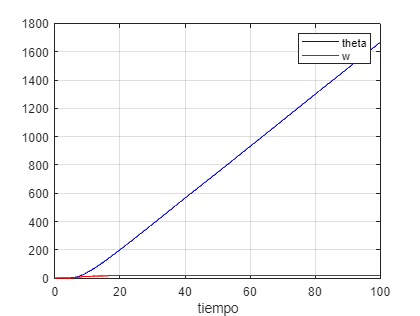

%solución del sistema con u=7.55 (valor donde el sistema rotará) indefinidamente
syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0.2; u=7.55;

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));


f = odeFunction([f1 f2],[x1 x2]);

h = 0.1;

tmin = 0;
tmax = 100;
tspan = tmin:h:tmax;

ci = [0 0]; 
[t,x] = ode45(f,tspan,ci);

theta = x(:,1);

w = x(:,2);

plot(t,theta,'b',t,w,'r'),

xlabel('tiempo'),
legend('theta','w')

grid,

- Indudablemente, se puede inferir de la gráfica presentada que la fuerza mínima necesaria para mantener el péndulo en un movimiento rotacional constante, es decir, para permitir que complete un giro completo, es de 7.55 N.

**2. Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada. El rango de entradas no debe superar el valor máximo calculado anteriormente.**

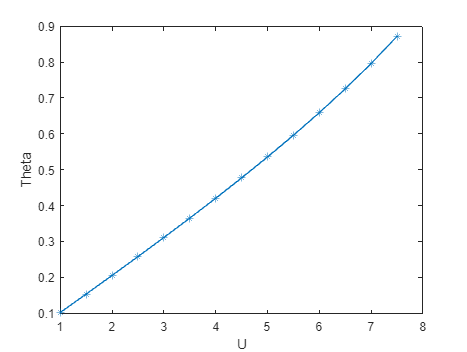

%Analizar el sistema al cambiar los valores de u

clc 
clear

syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0.2; 

u=1:0.5:7.55;

sol=[];

for i=1: numel(u)

    U=u(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(U/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.01;
    
    tspan=0:h:100;

    ci=[0 0];

    [t,sol{i}]= ode45(F, tspan, ci);

    theta(i) = sol{i}(end,1);
     
end

plot (u,theta, '*-');
xlabel ('U');
ylabel ('Theta');

- En esta gráfica podemos observar que la fuerza aplicada en el péndulo y el ángulo mantienen una relacion directa, pues a medida que se aumentan los valores de entrada de la fuerza, el ángulo también incrementa sus valores

**3. Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. Interpretar el resultado. ¿Para qué valor de la frecuencia angular inicial el péndulo da una vuelta? ¿Para qué valor da tres vueltas? Observar los puntos de equilibrio.**

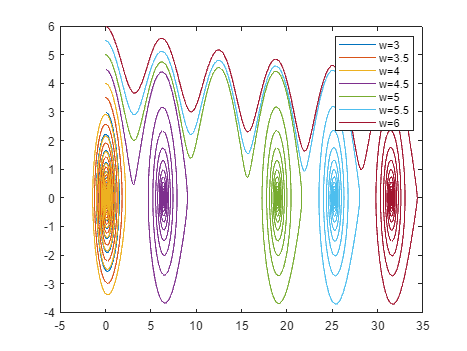

%Analizar el sistema al cambiar los valores de w

clc 
clear



m= 1; g=9.8; l=2; f=0.2; u=1;

w0=3:0.5:6;


for i=1: numel(w0)

   syms x1(t) x2(t)

    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.01;
    
    tspan=0:h:100;

    ci=[0 w0(i)];

    [t,sol]= ode45(F, tspan, ci);

    theta = sol(:,1);
     w = sol(:,2);

    plot (theta,w);
hold on
     
end

hold off


legend ('w=3','w=3.5','w=4', 'w=4.5','w=5','w=5.5','w=6')

- En este caso podemos evidenciar que  para las condiciones iniciales de 4.5 y 5, el péndulo da una y tres vueltas respectivamente

`4. `**Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad. Interpretar el resultado. Observar los tres únicos puntos de equilibrio.**

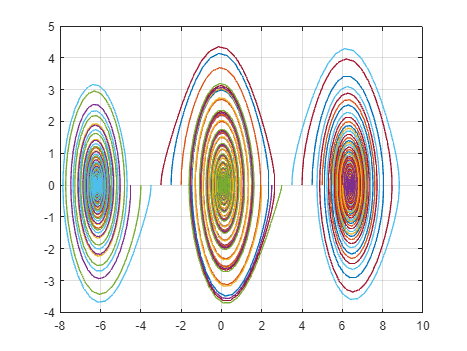

%Analizar el sistema al cambiar los valores de w

clc 
clear all


m= 1; g=9.8; l=2; f=0.2; u=1;

teta0=-6:0.5:6;


for i=1: numel(teta0)

   syms x1(t) x2(t)

    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:500;

    ci=[teta0(i) 0];

    [t,sol]= ode45(F, tspan, ci);

     w = sol(:,1);
     teta = sol(:,2);

    plot (w,teta);
  hold on 
     
end
grid,
hold off

- De esta gráfica podemos concluir que: 

               - Para las condiciones entre -8 y -3.5 el punto de equilibrio es -6

               - Para las condiciones entre -3 y 3 el punto de equilibrio es 0

               - Para las condiciones entre 3.5 y 9 el punto de equilibrio es 6.3

**5. Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *****u***** = 1 y condiciones iniciales iguales a cero.**

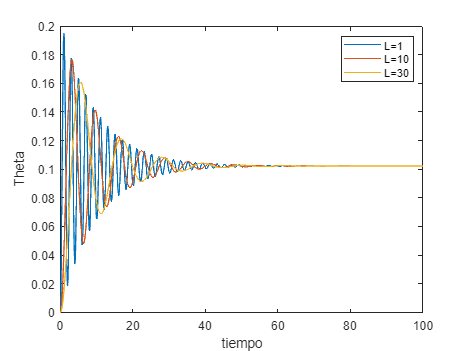

clc 
clear

syms x1(t) x2(t)

m= 1; g=9.8; u=1; f=0.2; 

l= [1 10 30];

sol=[];

for i=1: numel(l)

    L=l(i);
    F1= x2;
    F2 = (-g/L)*sin(x1)-(f/m)*x2+(u/(m*L));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:100;

    ci=[0 0];

    [t1,sol]= ode45(F, tspan, ci);

    theta = sol(:,1);

    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
    
end
legend ('L=1','L=10','L=30')
hold off

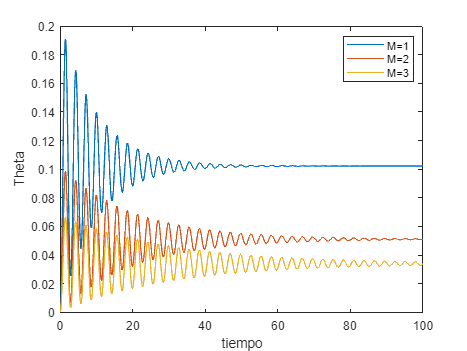

clc 
clear

syms x1(t) x2(t)

l= 2; g=9.8; u=1; f=0.2; 

m= [1 2 3 ];

sol=[];

for i=1: numel(m)

    M=m(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f/M)*x2+(u/(M*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:100;

    ci=[0 0];

    [t1,sol]= ode45(F, tspan, ci);

    theta = sol(:,1);

    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
         
end

legend ('M=1','M=2','M=3')
hold off

- Mientras la masa aumenta el péndulo tarda más en estabilizarse, y el valor donde se estabiliza es cada vez menor.  

**7. Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *****u***** = 1 y condiciones iniciales iguales a cero.**

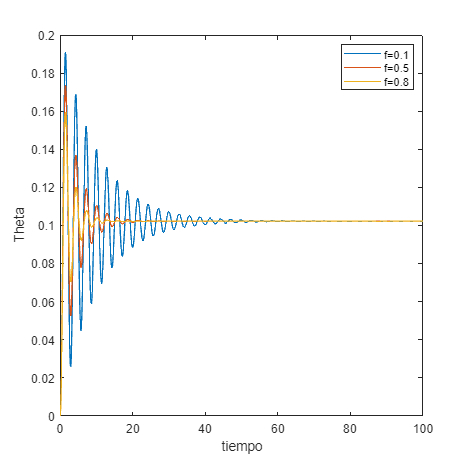

clc 
clear

syms x1(t) x2(t)

l= 2; g=9.8; u=1; m=1; 

f= [0.2 0.5 0.8];

sol=[];

for i=1: numel(f)

    f(i);
    F1= x2;
    F2 = (-g/l)*sin(x1)-(f(i)/m)*x2+(u/(m*l));

    F =odeFunction ([F1 F2], [x1 x2]);

    h=0.1;
    
    tspan=0:h:100;

    ci=[0 0];

    [t1,sol]= ode45(F, tspan, ci);

    theta = sol(:,1);

    plot (t1,theta);
    xlabel ('tiempo');
    ylabel ('Theta');
    hold on
     
end

legend ('f=0.1','f=0.5','f=0.8')
hold off

- Para este caso se puede ver que el número de oscilaciones está relacionado con la fricción viscosa, pues a medida que esta aumenta su valor, las oscilaciones en el péndulo disminuyen, sin embargo el péndulo se estabiliza en el mismo valor. 

**8. Si f = 0, u = 0 (movimiento libre no amortiguado) y la posición angular inicial ω(0) es menor a unos 30° (0.5 radianes, aproximadamente), se puede aproximar el seno del ángulo en radianes por el ángulo (comprobar con la calculadora o MATLAB) y el modelo es lineal. Obtener la ecuación de estado, pasar a la ecuación diferencial homogénea con coeficientes constantes y resolverla analíticamente. ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad? Comprobar los resultados con MATLAB**

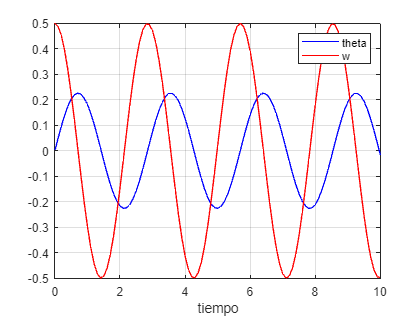

syms x1(t) x2(t)

m= 1; g=9.8; l=2; f=0; u=0;

f1 = x2;
f2 = (-g/l)*sin(x1)-(f/m)*x2+(u/(m*l));


f = odeFunction([f1 f2],[x1 x2]);

h = 0.1;

tmin = 0;
tmax = 10;
tspan = tmin:h:tmax;

ci = [0 0.5]; 
[t,x] = ode45(f,tspan,ci);

theta = x(:,1);
w = x(:,2);

plot(t,theta,'b',t,w,'r'),

xlabel('tiempo'),
legend('theta','w')

grid,

La representación gráfica exhibe movimientos pendulares que siguen un patrón armónico, lo cual es congruente con la suposición de que el ángulo de oscilación es pequeño.

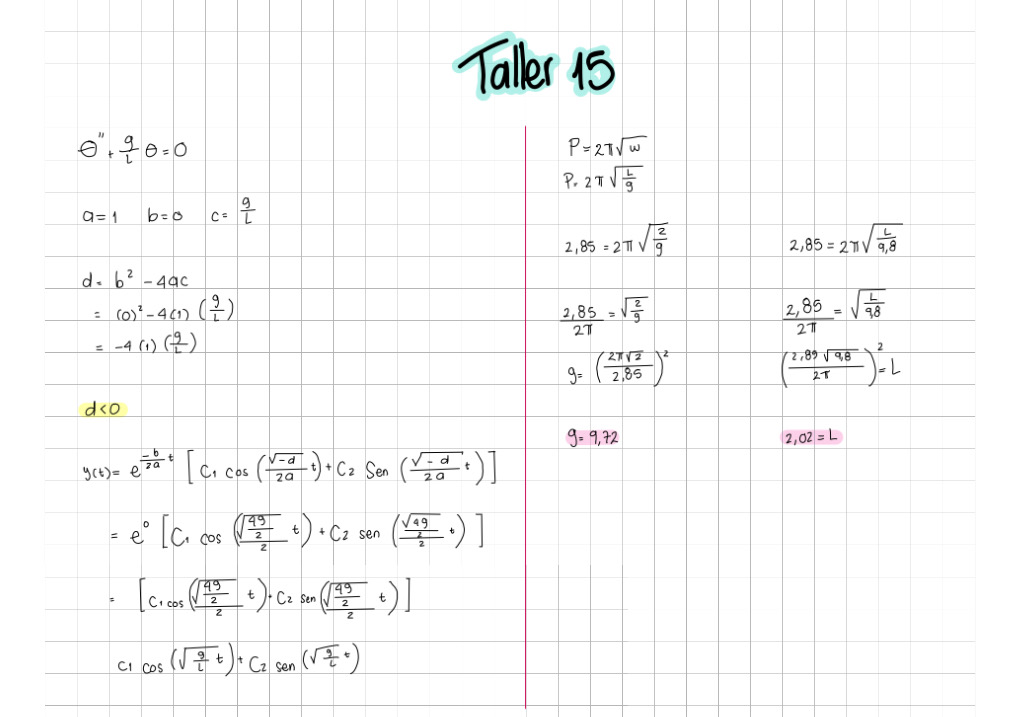

**9. Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *****l***** = 2 y *****g***** = 9.8, hallar aproximadamente por tanteo los valores de *****f***** y *****m*****. Explicar el procedimiento. Tener en cuenta los resultados de las tareas 6 y 7.**

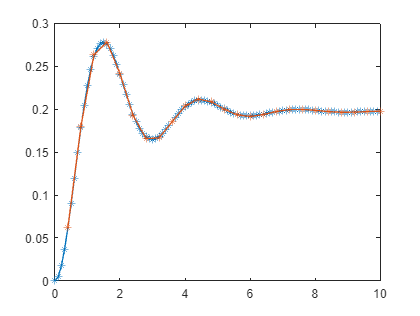

clear all;

t1 = [0.4 0.8 1.2 1.6 2 2.4 2.8 3.2 3.6 4 4.4 4.8 5.2 5.6 6 6.4 6.8 7.2 7.6 8 8.4 8.8 9.2 9.6 10];

ang= [0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];

m= 0.52; 
f= 0.63; 
g= 9.8; 
l= 2; 
u = 1; 

     syms x1(t) x2(t)  

     f1 = x2;  
     f2 = -((g/l)*sin(x1))-((f/m)*x2)+(u/(m*l));

     F = odeFunction([f1 f2],[x1 x2]);  

     h = 0.1; 

    tmin = 0;
    tmax = 10;
    tspan = tmin:h:tmax; 

    ci = [0 0]; 

    [t,sol] = ode45(F,tspan,ci); 

    teta = sol(:,1); 
   
plot(t,teta,'*-')
hold on
plot(t1,ang,'*-')
hold off

Los valores de masa y friccíon viscosa para los cuales el péndulo se comporta cómo el modelo dado son 0.52 y 0.63 respectivamente. Para realizar el tanteo se tuvo en cuenta que en el punto 6, a menor masa la apmilutud de las oscilaciones era mayor, y en el caso de la fricción se analizo en el numeral 7 que mientras el coeficiente aumentaba, las osilaciones del péndulo disminuian. 

**10. Montar un experimento en casa de un péndulo con entrada igual cero y un ángulo inicial entre 20 y 60°, y hallar los parámetros *****l *****y *****f***** si se conocen *****m***** y *****g*****. Es decir, suponer que no se sabe la longitud. Al final, mostrar la discrepancia de la longitud. ¿Por qué si no hay entrada el experimento no sirve para hallar *****f***** y *****m***** como en la tarea anterior?**

Se realizo un experimento en clase con ayuda de la profesora. En este se tomaron varios videos donde re registran el timepo que tarda el pendulo en llegar aproximadamente a 0. Ademas de esto se le agregaron varios pesos, eso causo los diferentes tiempos en el experimento. Se adjuntaran fotos del experimento y sus respuestas obtenidas 

**En este experimento se tomaron los siguentes datos.**

    Largo de pendulo: 85 cm

    Condicion inicial 1: 30°

    Condicion inicial 2 : 45° 

Adjunto a continuacion evidencias de los resultados con su respectivo tiempo

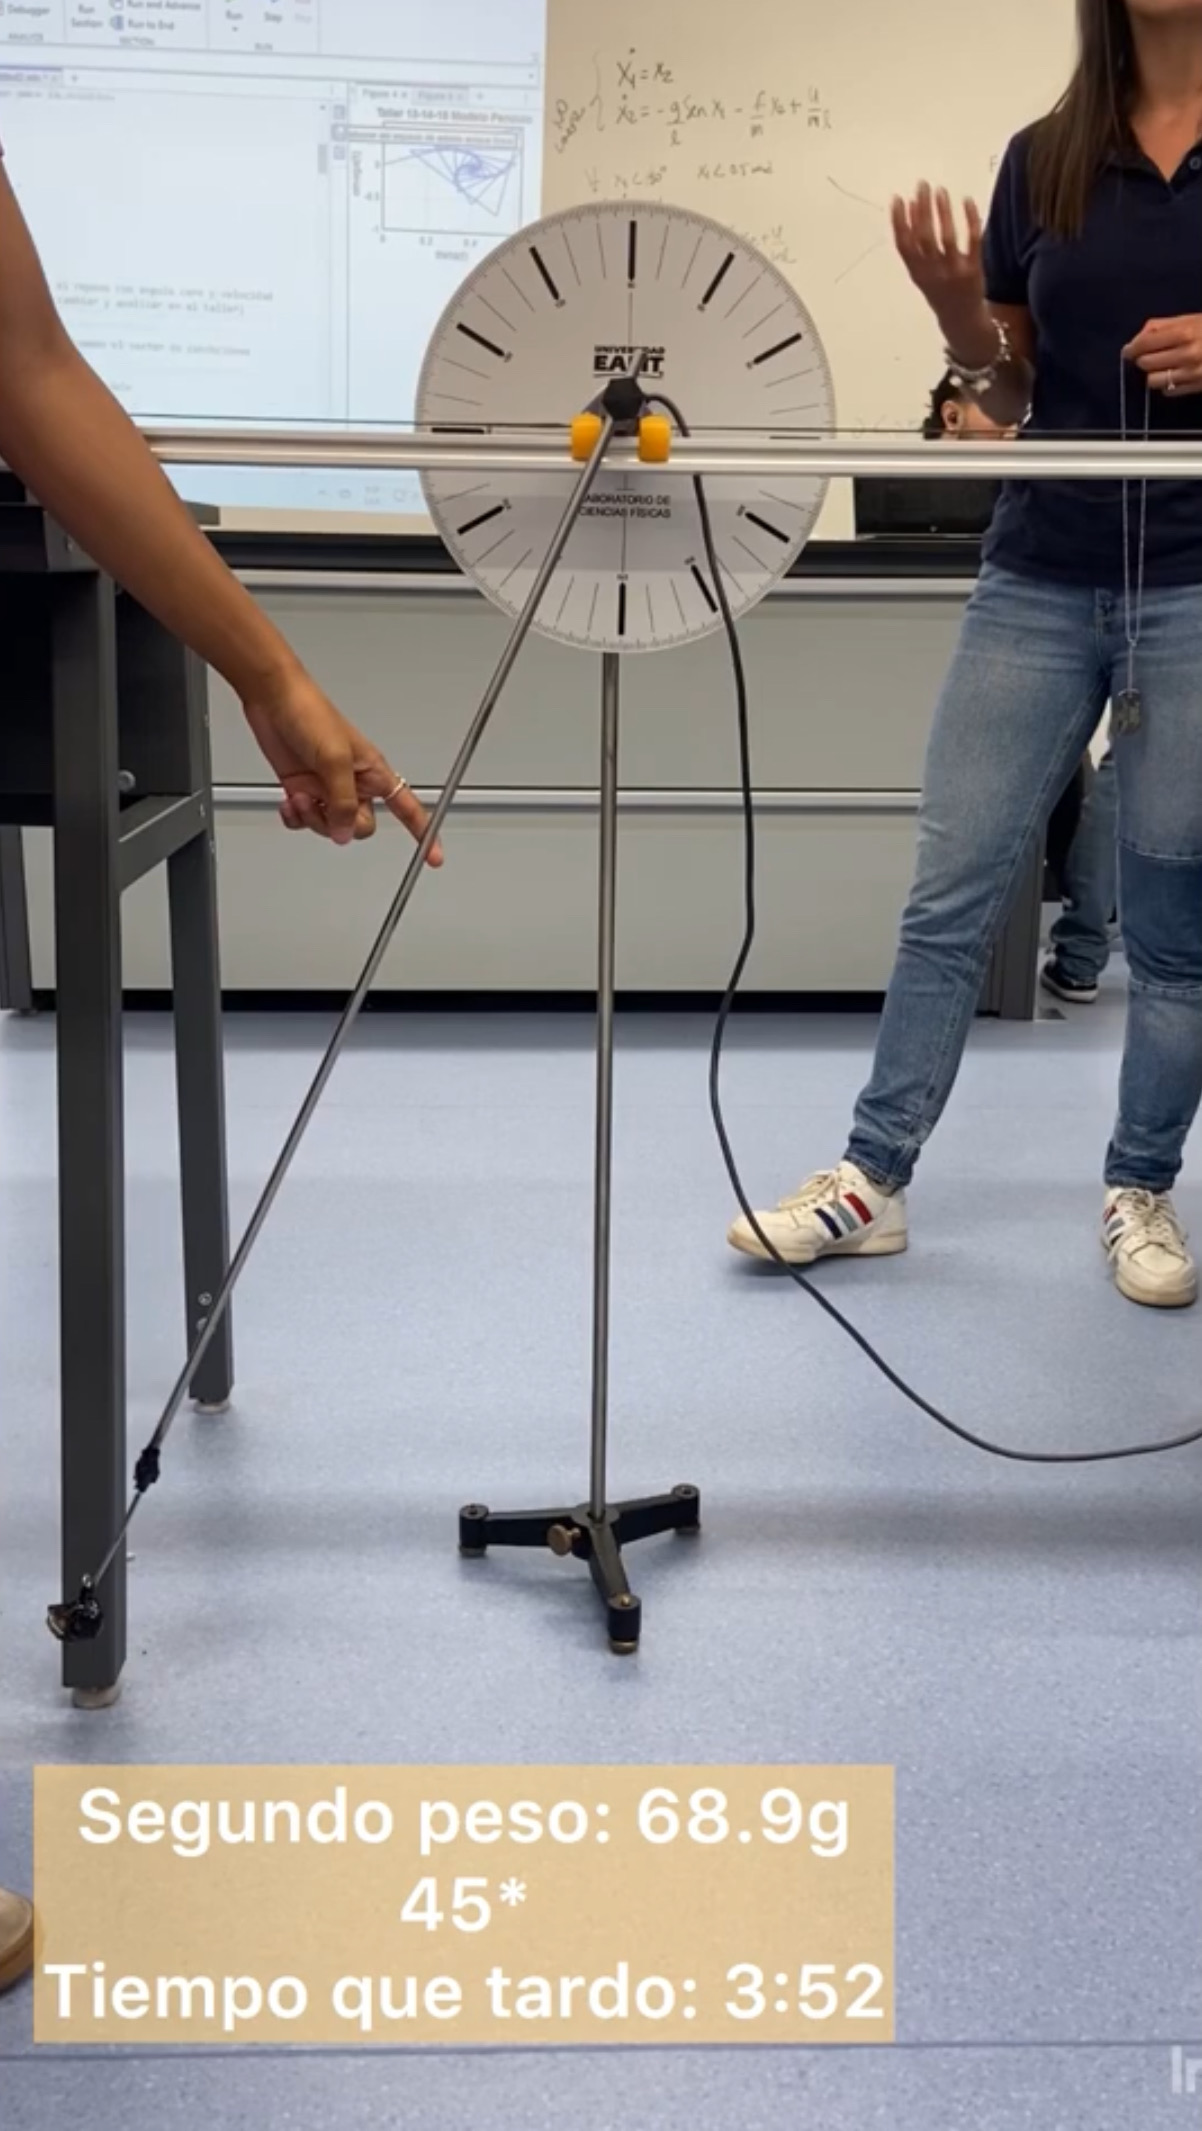

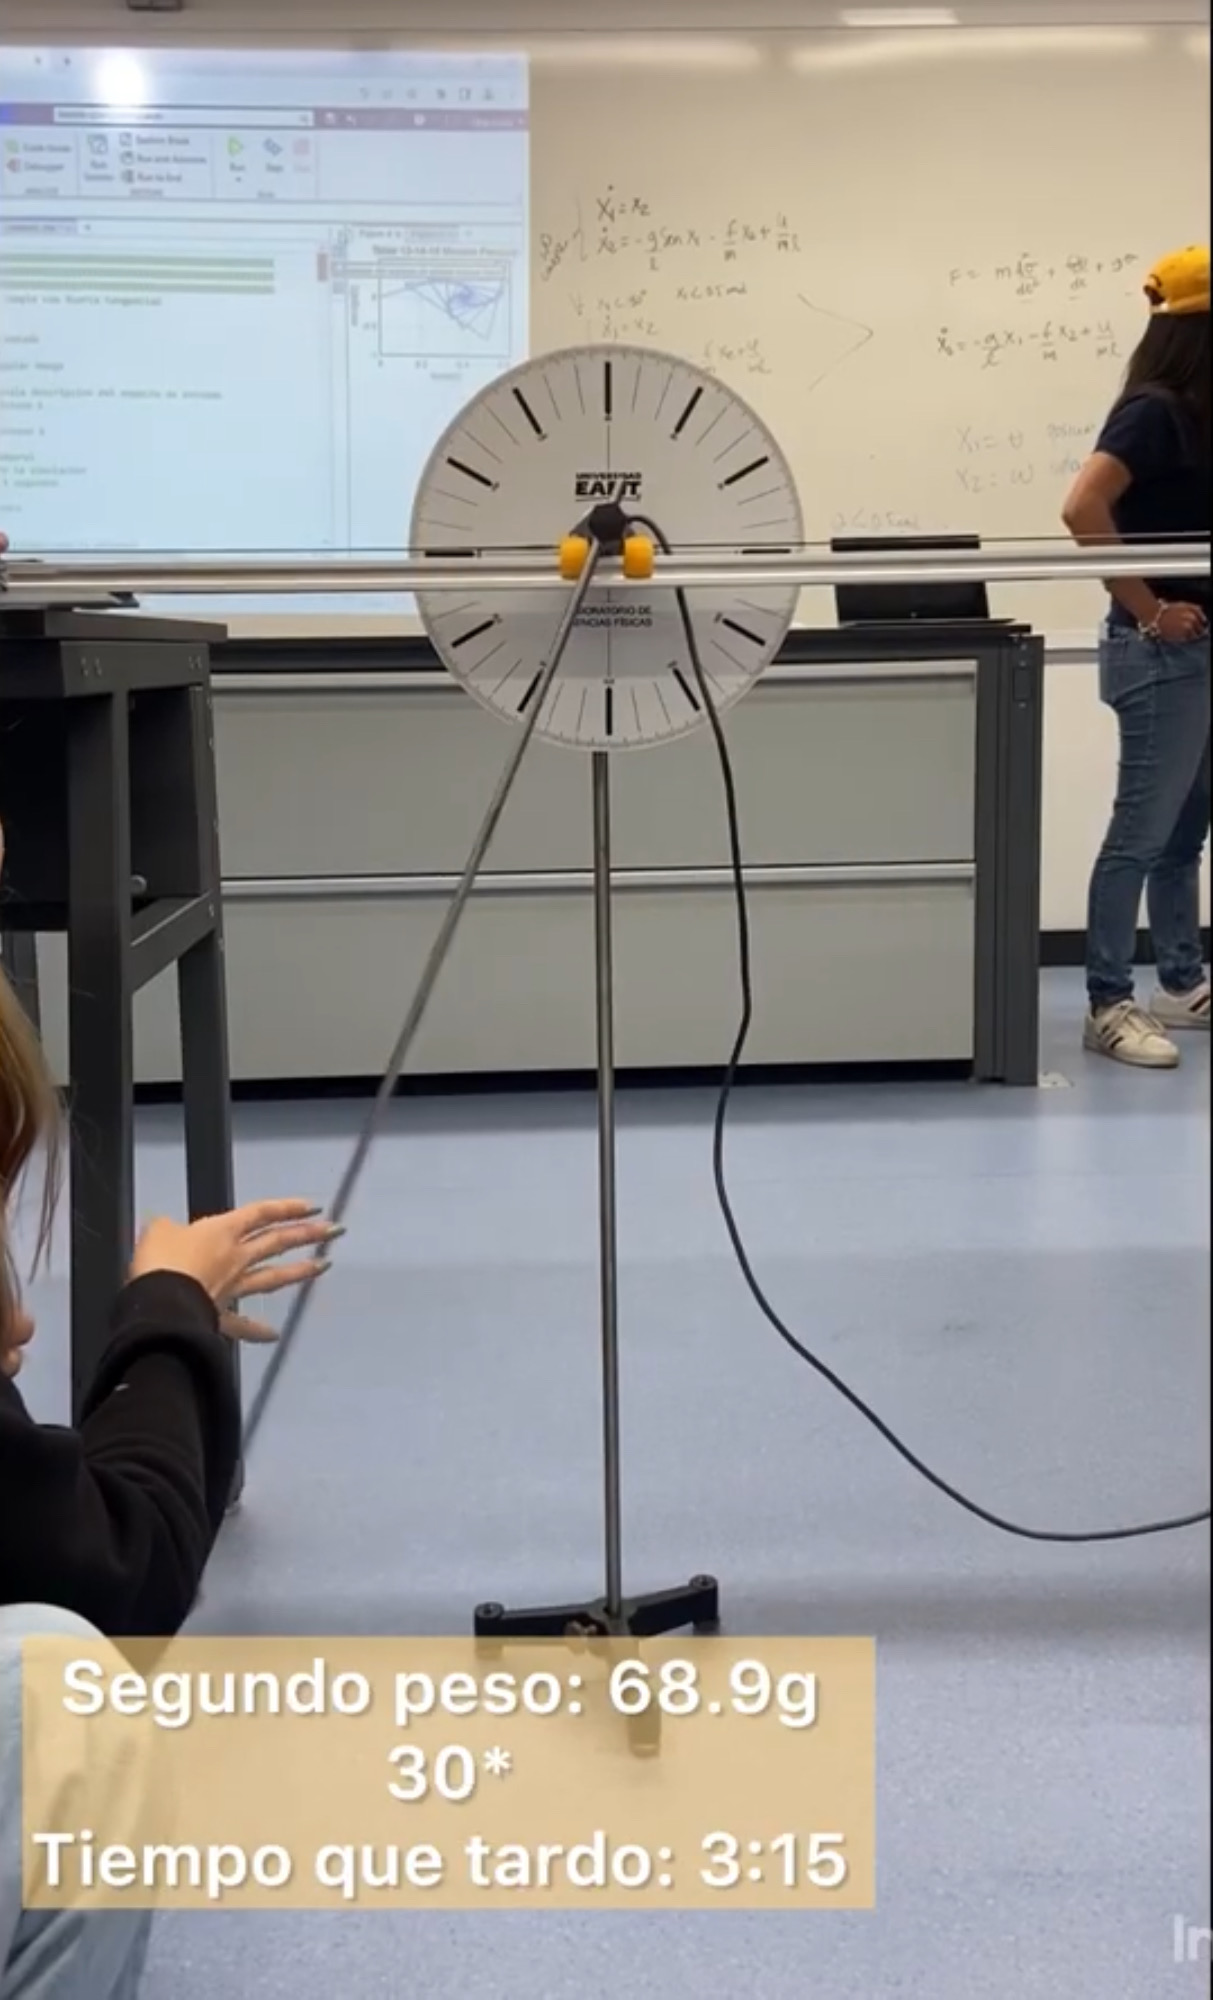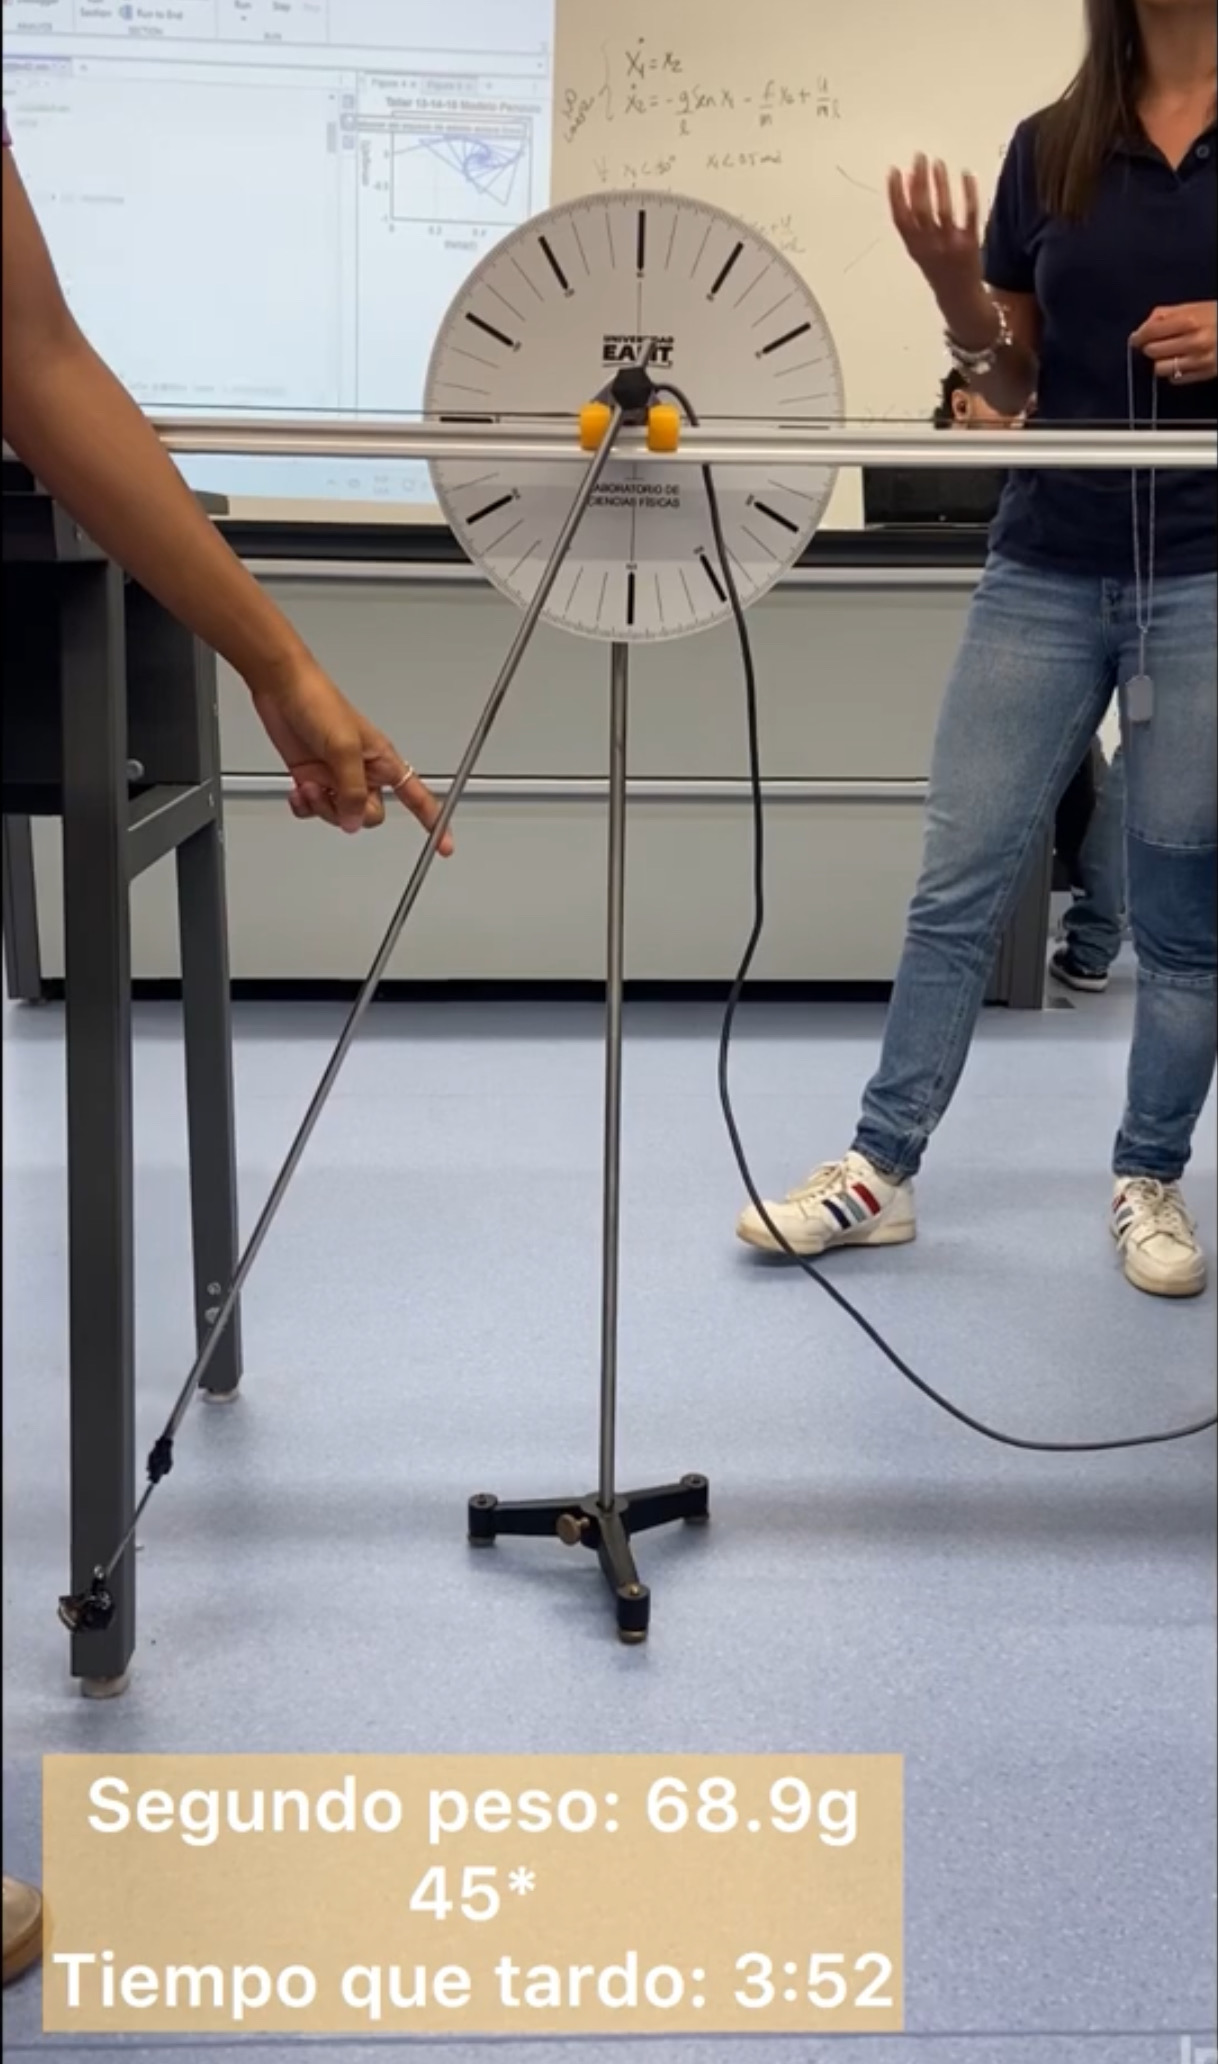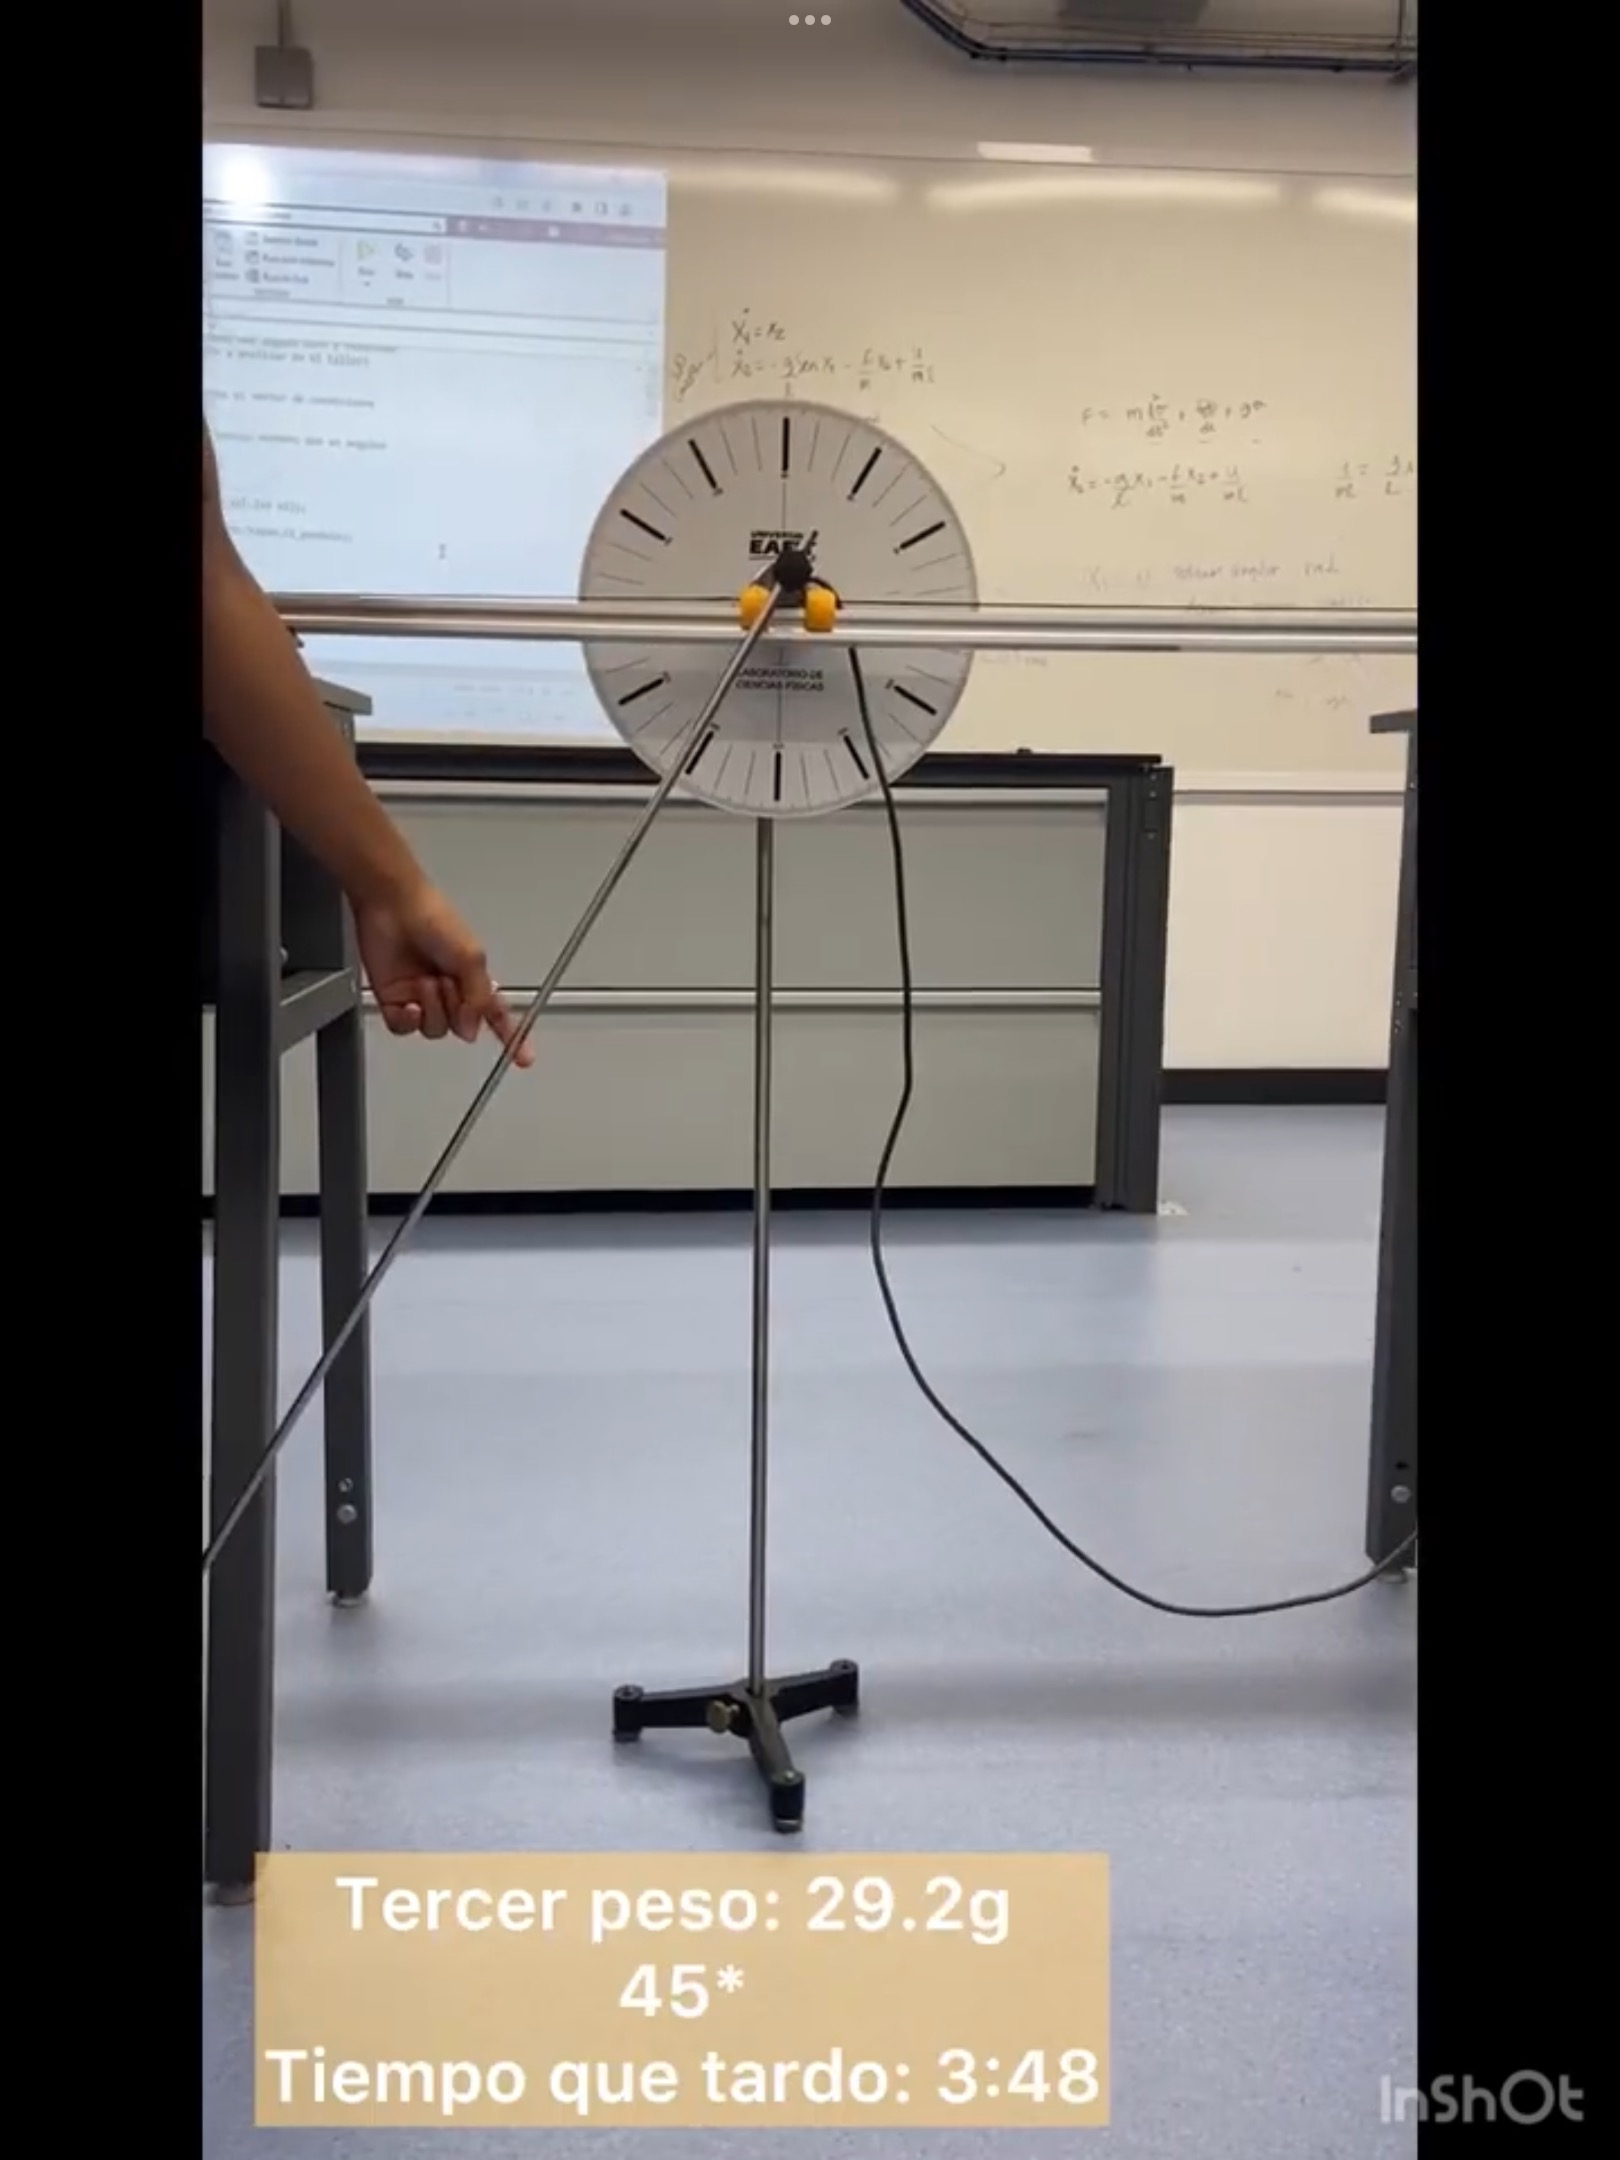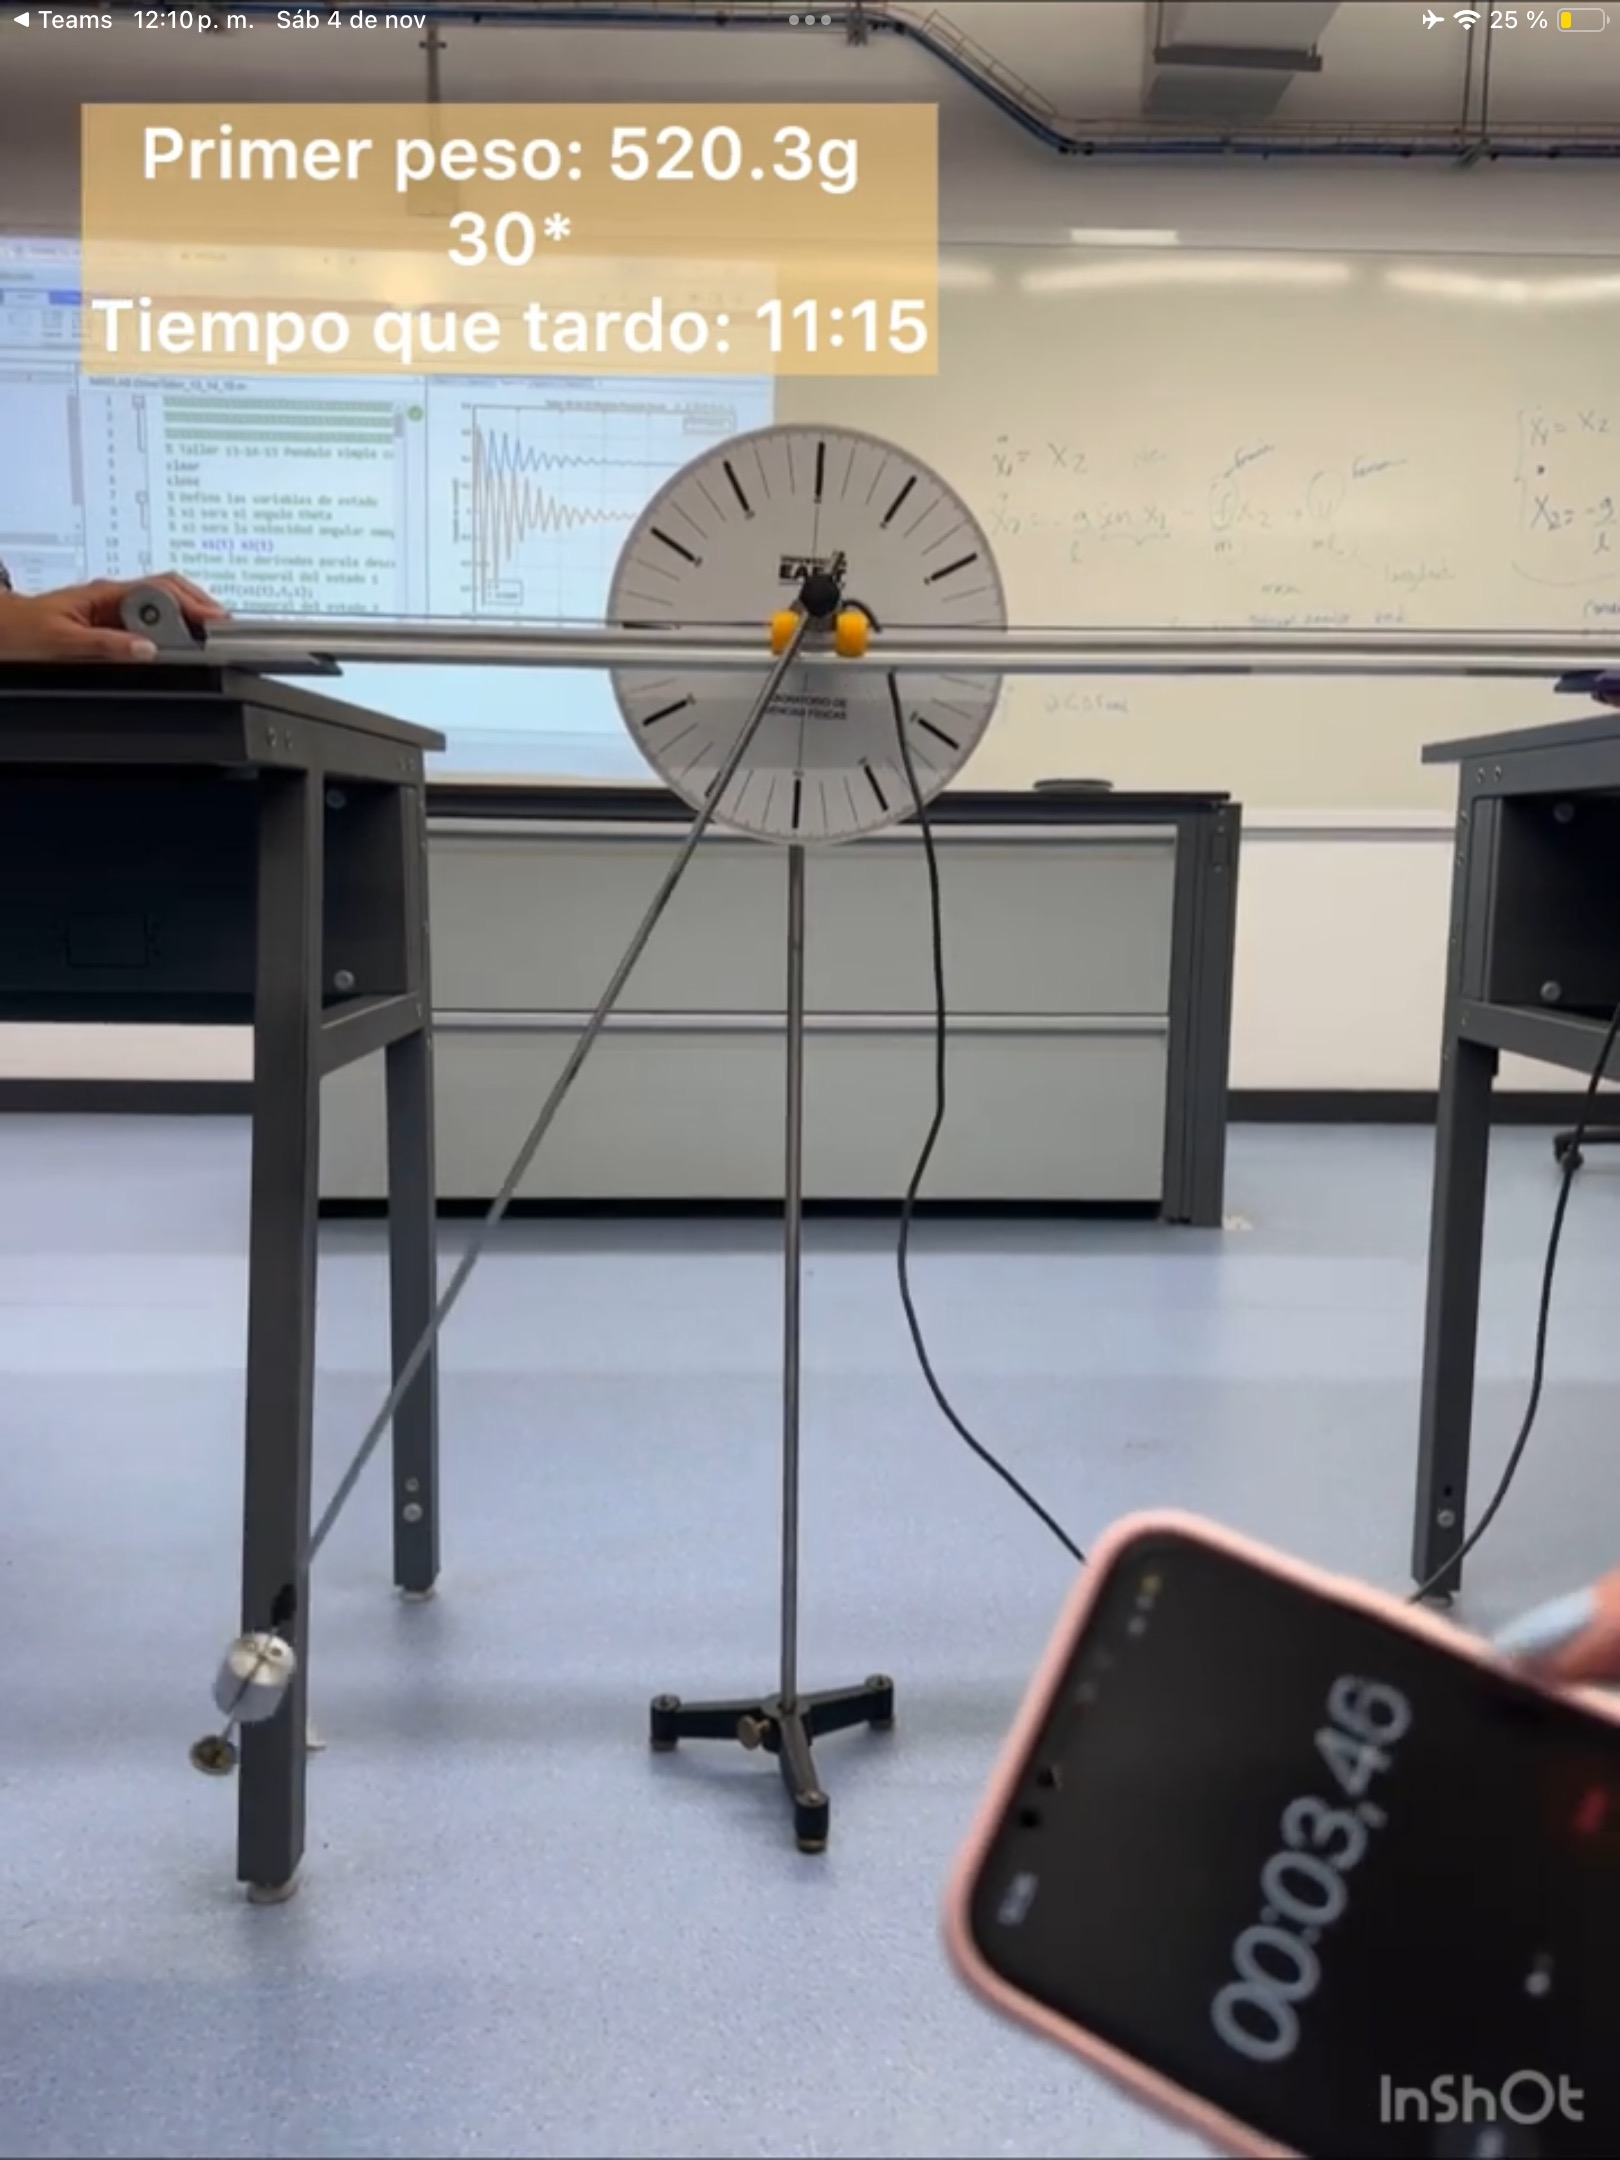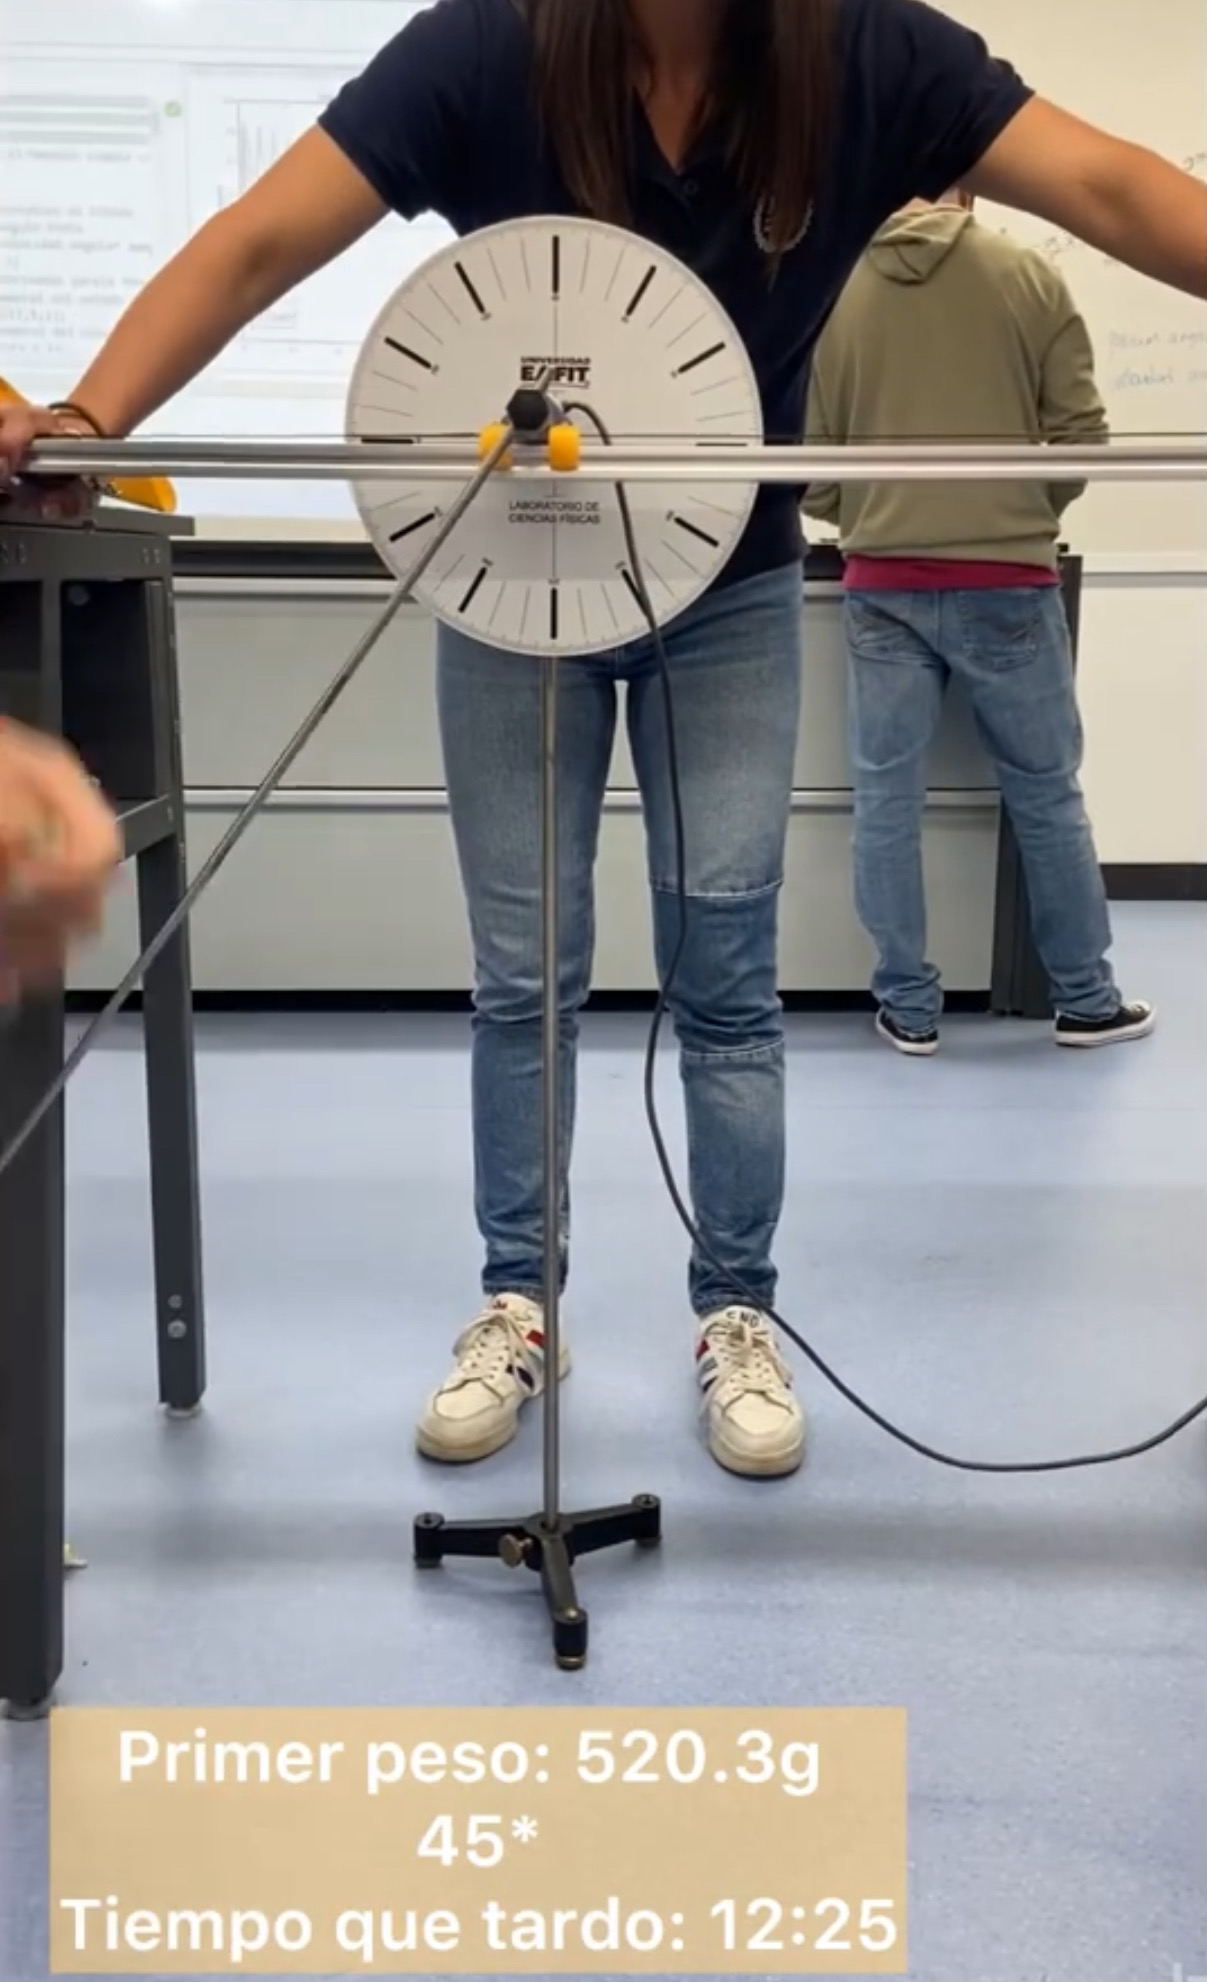

En ausencia de una fuerza impulsora, el péndulo experimentará gradualmente una disminución en su amplitud hasta que se detenga por completo. Este fenómeno se debe al efecto de la fricción viscosa, que disipa progresivamente la energía del péndulo, resultando en una reducción constante de la amplitud de sus oscilaciones con el transcurso del tiempo.